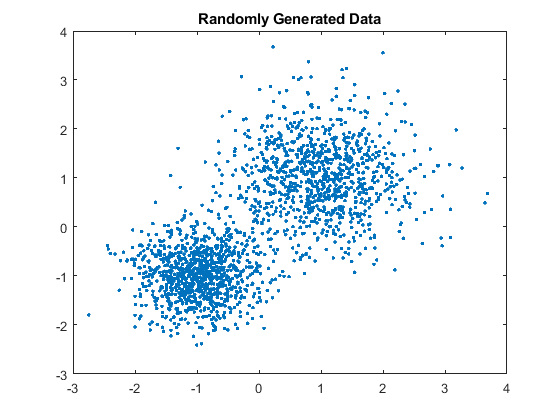

clear
clear;
%Example from MATLAB for testing
rng default; % For reproducibility
X = [randn(1000,2)*0.75+ones(1000,2);
    randn(1000,2)*0.5-ones(1000,2)];

figure;
plot(X(:,1),X(:,2),'.');
title 'Randomly Generated Data';

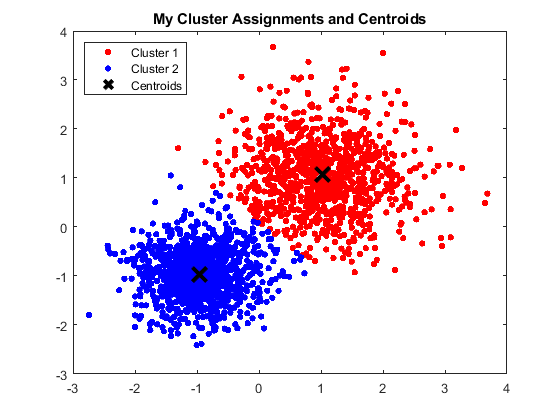

[centers,clusters,sum_d,dcen,dclu] = k_means2(2,X,1000);

% Plot the Final Data points
figure;
plot(X(clusters==1,1),X(clusters==1,2),'r.','MarkerSize',12)
hold on
plot(X(clusters==2,1),X(clusters==2,2),'b.','MarkerSize',12)
plot(centers(:,1),centers(:,2),'kx','MarkerSize',15,'LineWidth',3);
legend('Cluster 1','Cluster 2','Centroids','Location','NW');
title 'My Cluster Assignments and Centroids'
hold off


%Make a movie and save a video
V = VideoWriter('kNN.mp4');
open(V);
g = figure;
g.Visible = 'off';
axis tight manual
% gca.NextPlot = 'replaceChildren';
frames = size(dclu,2);
M(frames) = struct('cdata',[],'colormap',[]);
iter_cnt = annotation('textbox',[0.75 0.75 0 0],'String','Iter = 1','FitBoxToText','on','FontSize',14);
iter_cnt.EdgeColor = 'none';

for jj=1:frames
    plot(X(dclu(:,jj)==1,1),X(dclu(:,jj)==1,2),'r.','MarkerSize',12);
    hold on
    plot(X(dclu(:,jj)==2,1),X(dclu(:,jj)==2,2),'b.','MarkerSize',12)
    plot(dcen(:,1,jj),dcen(:,2,jj),'kx','MarkerSize',15,'LineWidth',3);
    legend('Cluster 1','Cluster 2','Centroids','Location','NW');
    title('Cluster Assigments');
    iter_cnt = annotation('textbox',[0.75 0.25 0 0],'String',sprintf('Iter = %i',jj),'FitBoxToText','on','FontSize',14,'EdgeColor','none');
    iter_cnt.EdgeColor = 'none';
    hold off
    drawnow
    M(jj) = getframe;
    writeVideo(V,M(jj));
end
close(V);
g.Visible = 'on';
movie(M,5,0.5);

function [centers,clusters, sum_d,chng_centers,chng_clusters] = basic_weighted_k_means(k,A,max_iters)
        [m,n] = size(A);
        % do an initial cluster first
    % Start with K centers chosen randomly from the data
    centers = A(randperm(m, k),:);
    %keep track of clusters each point is in
    clusters = zeros(m,1);
    % change in clusters and centers
    chng_clusters = zeros(m,max_iters+1);
    chng_clusters(:,1) = clusters;
    chng_centers = zeros(k,n,max_iters+1);
    chng_centers(:,:,1) = centers;
    % repeat until convergence criteria met
    % cluster each point with the center closest to it
    j = 0;
    while j < max_iters %stopping criteria #1
        clch = false; %if anything changed clusters
        %keep track of number of points in each cluster
        cnt = zeros(k,1);
        % cluster each point with center closest to it
        % find centroid of each cluster and replace the set of old centers
        % with new ones
        centroids = zeros(k,n);
        for p=1:m
            %get the cluster the point is in
            [md,x] = min(sqrt(sum((centers-A(p,:)).^2,2)));
            if clusters(p) ~= x
                clch = true;
                clusters(p) = x;
            end
            % update the cluster count, centroid sum
            cnt(x) = cnt(x) + 1;            
            centroids(x,:) = centroids(x,:) + A(p,:);
        end 
        % divide each centroid by the total number of points to find the
        % actual centroid
        for w=1:k
            if cnt(w) ~= 0
                centroids(w,:) = centroids(w,:)./cnt(w);
            end
        end
        % if no points change cluster or centroids don't change, stop
        if(isequal(centroids,centers) || ~clch)
            chng_centers = chng_centers(:,:,1:j);%only return needed
            chng_clusters = chng_clusters(:,1:j);
            break
        else
            centers = centroids;
        end
        %save the values
        chng_clusters(:,j+1) = clusters;
        chng_centers(:,:,1+j) = centers;
        %next iteration
        j = j + 1;     
    end
    
    % the sum of point to center squared distances within clusters
    sum_d = zeros(k,1);
    for p=1:m
        for z = 1:k
            if(clusters(p) == z)
                g = A(p,:) - centers(z,:);
                sum_d(z) = sum_d(z) + g*g';
            end
        end
    end
    
end

% |Regular K-Means Algorithm
function [centers,clusters,sum_d,chng_centers,chng_clusters] = k_means2(k,A,max_iters)
    % Apply the k-means algorithm to A
    [m,n] = size(A);
    % Start with K centers chosen randomly from the data
    centers = A(randperm(m, k),:);
    %keep track of clusters each point is in
    clusters = zeros(m,1);
    % change in clusters and centers
    chng_clusters = zeros(m,max_iters+1);
    chng_clusters(:,1) = clusters;
    chng_centers = zeros(k,n,max_iters+1);
    chng_centers(:,:,1) = centers;
    % repeat until convergence criteria met
    % cluster each point with the center closest to it
    j = 0;
    while j < max_iters %stopping criteria #1
        clch = false; %if anything changed clusters
        %keep track of number of points in each cluster
        cnt = zeros(k,1);
        % cluster each point with center closest to it
        % find centroid of each cluster and replace the set of old centers
        % with new ones
        centroids = zeros(k,n);
        for p=1:m
            %get the cluster the point is in
            [md,x] = min(euclid_dist(centers,A(p,:)));
            if clusters(p) ~= x
                clch = true;
                clusters(p) = x;
            end
            % update the cluster count, centroid sum
            cnt(x) = cnt(x) + 1;            
            centroids(x,:) = centroids(x,:) + A(p,:);
        end 
        % divide each centroid by the total number of points to find the
        % actual centroid
        for w=1:k
            if cnt(w) ~= 0
                centroids(w,:) = centroids(w,:)./cnt(w);
            end
        end
        % if no points change cluster or centroids don't change, stop
        if(isequal(centroids,centers) || ~clch)
            chng_centers = chng_centers(:,:,1:j);%only return needed
            chng_clusters = chng_clusters(:,1:j);
            break
        else
            centers = centroids;
        end
        %save the values
        chng_clusters(:,j+1) = clusters;
        chng_centers(:,:,j+1) = centers;
        %next iteration
        j = j + 1;     
    end
    
    % the sum of point to center squared distances within clusters
    sum_d = zeros(k,1);
    for p=1:m
        for z = 1:k
            if(clusters(p) == z)
                g = A(p,:) - centers(z,:);
                sum_d(z) = sum_d(z) + g*g';
            end
        end
    end
end

%get the haversine distance (used for population statistics)
function dist = hav_dist(A,B,R)
    %if no radius specified, use the earth radius in meters
    if nargin==2
        R = 6371000;
    end
    if size(A) ~= size(B)
        disp('Nonmatching vector dimensions')
        return
    end
    phi1 = A(1)*pi/180; %convert to radians
    phi2 = B(1)*pi/180;
    delta = (A0B)*pi/180;
    a = (sin(delta(1)/2)).^2+cos(phi1)+cos(phi2)*((sin(delta(2)/2)))^2;
    dist = round(2*R*atan2(sqrt(a),sqrt(1-a)),2);
end

%get the euclidean distance
%two vectors of same length
function dist = euclid_dist(A,B)
    if size(A) ~= size(B)
        disp('Nonmatching vector dimensions')
        return
    end
    dist = sqrt(sum((A-B).^2,2));
end